close all
clear
clc


c = 3e8;

## Упрощенная блок-схема велорадара

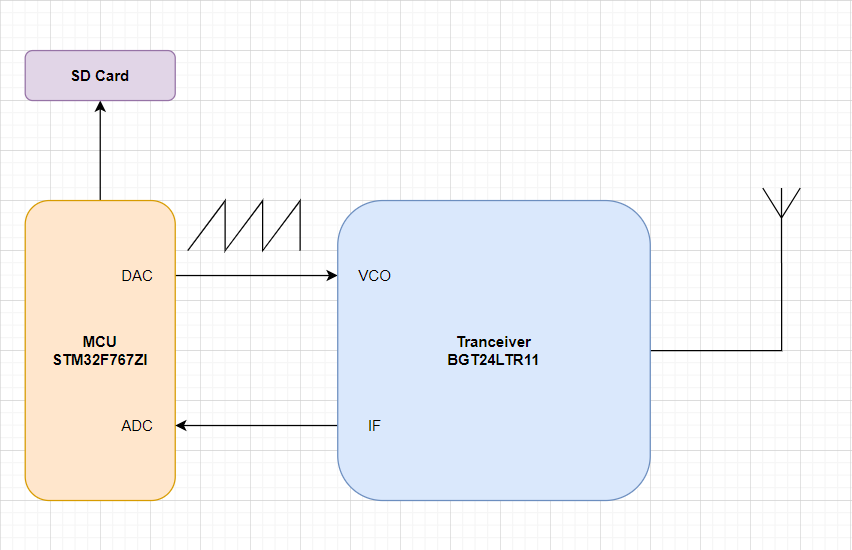

## Параметры велорадара:

Полоса ЛЧМ-сигнала

B = 100e6;

Несущяя частота

f0 = 24e9;

Период повторения импульсов (Repition Period Interval)

T = 100e-6;

Максимальная требуемая дальность

Rmax = 180;

Разрешяющяя способность по дальности

dR = c/2/B;

Чтобы обеспечить необходимую дальность, рассчитаем необходимое количество точек дя БПФ (рассматриваем реальный сигнал).

Зная частоту ПЧ на выходе трансивера, мы можем определить дальность по формуле:

 $R=\frac{f_{\mathrm{if}} \cdot c\cdot T}{2\cdot B}$                                                                                                                                                                               (1)

Максимальна частота ПЧ будет равна половине частоты Найквиста: $f_{\mathrm{if}\_\mathrm{max}} =\frac{f_s }{2}$                                                                 (2)

Зная частоту дискретизации и период повторения импульсов мы можем определить количество точек БПФ. Количество точек БПФ должно быть степени 2 (для упрощения алгоритмической части и из-за апаратных осбенностей).

$f_s \ge \frac{N_{\mathrm{fft}} }{T}\Longrightarrow f_s \ge \frac{2^n }{T}$                                                                                                                                                                      (3)

Теперб подставляя (3) в (2) и (2) в (1) получим выражение для нахождения количества точек БПФ необходимых для обеспечения максимальной дальности Rmax:

Nfft = 2^nextpow2(4*B*Rmax/c);

Теперь мы можем определить необходимую частоту дискретизации:

fs = Nfft/T;

Расстояние между сэмлами в частотной области будет равно (разрешающяя способность БПФ):

df = fs/Nfft;

Теперь подставив разрешающую способность БПФ в (1) получим реальную разрешающую способность по дальности:

dR_real = df*c*T/2/B;

Рассмотрим данную матрицу где вдоль Fast time ложаться сэмплы за один период сигнала с частотой дискретизации fs. Вдоль Slow time оси ложаться периоды сигнала на интервале когерентного наблюдения (coherent period interval)  с частотой дискретизации равной PRF (pulse repitition frequency), который определяется по следующей формуле:

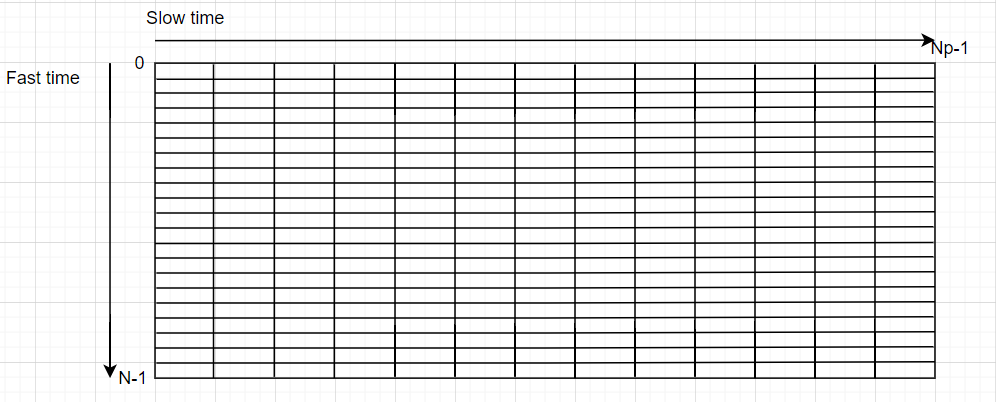

PRF = 1/T;
Np = 64;
CPI = Np*T;

Отсюда видно, что максимальная частота допплера должна быть меньше или равна частоте дискретизации вдоль slow time оси:

fd_max = PRF/2;

Из формулы для определения допплеровского смещения

$f_d =\frac{2\cdot v\cdot c}{f_0 }$                                                                                                                                                                     (4)

мы можем определить максимальную определяемую скорость:

vmax = PRF*c/4/f0;